% sistema massa-molla-smorzatore

% parametri
m = 1; c = 0.5; k = 2; % m=massa, c=coef. di attrito, k=cost. elastica

A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0];
D = 0;

sys = ss(A, B, C, D);
sys_tf = tf(sys); %fdt

display(sys);


sys =
 
  A = 
         x1    x2
   x1     0     1
   x2    -2  -0.5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


display(sys_tf);


sys_tf =
 
         1
  ---------------
  s^2 + 0.5 s + 2
 
Continuous-time transfer function.


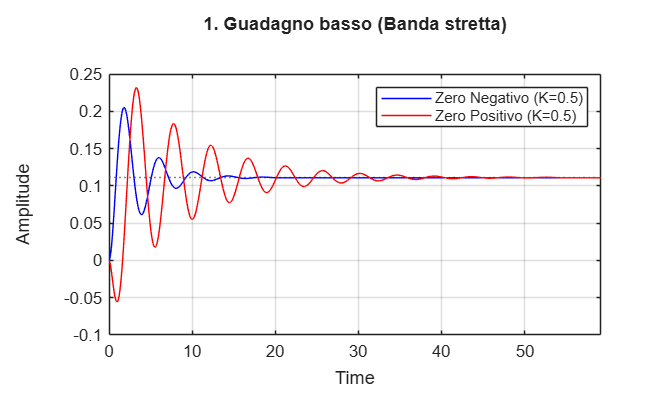


% controllori diversi per il segno dello zero
s = tf('s');
R_buono   = (s + 1) / (s + 2); % zero negativo
R_cattivo = (1 - s) / (s + 2); % zero positivo

% test di un guadagno basso e uno alto
K_low = 0.5;   % banda bassa
K_high = 5;    % banda alta

% --- Scenario 1: guadagno basso ---
% zero positivo
L_buono_low = K_low * R_buono * sys_tf;
W_buono_low = feedback(L_buono_low, 1);

% zero negativo
L_cattivo_low = K_low * R_cattivo * sys_tf;
W_cattivo_low = feedback(L_cattivo_low, 1);

% --- Scenario 2: guadagno alto ---
% zero negativo
L_buono_high = K_high * R_buono * sys_tf;
W_buono_high = feedback(L_buono_high, 1);

% zero positivo
L_cattivo_high = K_high * R_cattivo * sys_tf;
W_cattivo_high = feedback(L_cattivo_high, 1);

% risposta al gradino
figure;
hold on;
step(W_buono_low, 'b');
step(W_cattivo_low, 'r');
title('1. Guadagno basso (Banda stretta)');
grid on; 
legend('Zero Negativo (K=0.5)', 'Zero Positivo (K=0.5)');

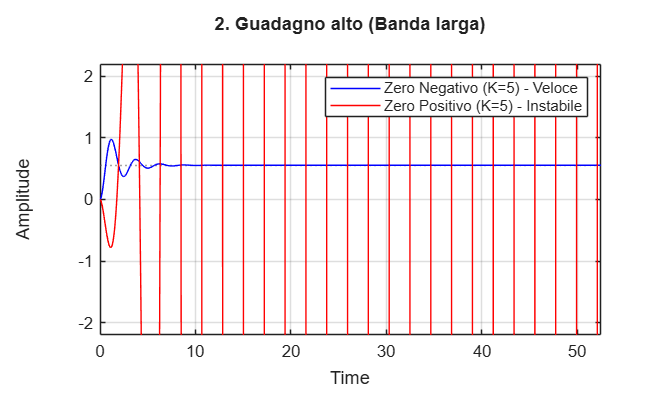


figure;
hold on;
step(W_buono_high, 'b');
step(W_cattivo_high, 'r');
title('2. Guadagno alto (Banda larga)');
legend('Zero Negativo (K=5) - Veloce', 'Zero Positivo (K=5) - Instabile');
grid on;
ylim([-2 2]);